# P03: Sistemas de inferencia difusos (FIS)

**Equipo:**

- Calixtro Maldonado Said Josue

- Contreras Alvarado Wendy Linette

- Cruz de los Santos Bladimir

- López López Alan Rodrigo

- Plata Guzmán Valeria Denisse

## Objetivos

- Implementar sistemas de inferencia difusos, utilizando MATLAB

- Decodificar sistemas de inferencia difusos implementados en Simulink

## Introducción

El método Tsukamoto del sistema de inferencia difusa es también uno de los métodos para la toma de decisiones. Especialmente en muchas incertidumbres y situaciones de vaguedad, este método es muy flexible y tiene tolerancia para cualquier dato existente. 

El sistema de inferencia difusa utiliza la monotonía del razonamiento en el proceso de resolución de problemas. El funcionamiento de este método es utilizar los datos de producción, inventario y demanda como entrada y luego procesados a través de las tres etapas del proceso para optimizar la cantidad de la entrada del tercero. Las siguientes tres etapas de FIS Tsukamoto, son Fuzzificación, Inferencia y Defuzzificación:

### A. Fuzzificación

Fuzzification es el proceso de convertir variables no difusas (variables numéricas) en variables difusas (variables lingüísticas). Primero se deben definir las variables que se utilizarán, como la demanda variable, el inventario y la producción. Cada variable tiene un conjunto difuso. Por ejemplo, para el inventario variable, el conjunto difuso usado es Inferior, Moderado y Arriba. Luego, después de eso, busque el valor de pertenencia de cada conjunto difuso, en cada variable. Valor de membresía obtenido al representar cada conjunto difuso con una función de membresía. Hay cinco funciones que se pueden utilizar que son, la representación triangular, la curva trapezoidal, la curva gaussiana, curva de campana y la curva sigmoide.

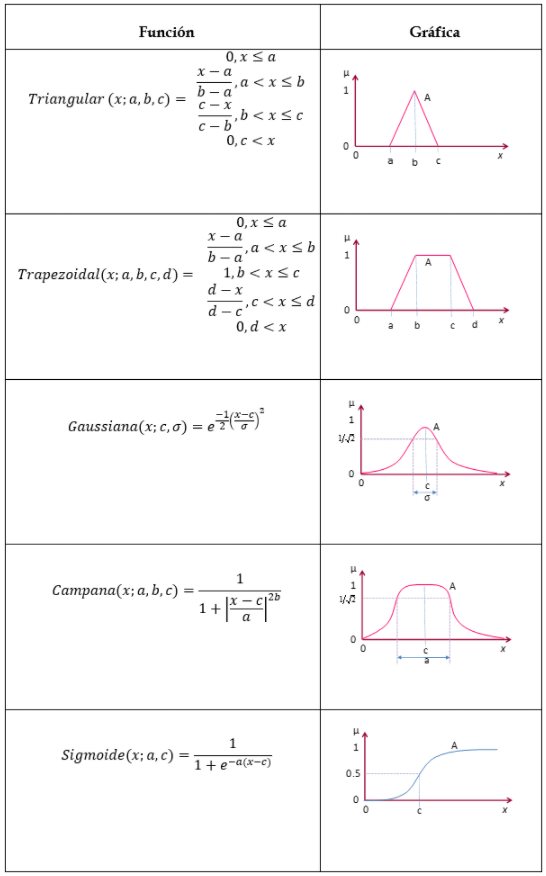

### B. Inferencia

La inferencia es el proceso de combinar muchas reglas basadas en los datos disponibles. El sistema de inferencia difusa recibe entradas nítidas. Luego, esta entrada se envía a una base de conocimientos que contiene n reglas difusas en forma de SI-ENTONCES. Después de determinar las reglas que se utilizarán, calcule el valor de la membresía antecedente o la resistencia al fuego (α) y el valor estimado de los bienes que se fabricarán (z) de cada regla, utilizando el valor de membresía de cada conjunto difuso.

### C. Defuzzyfication

Determina que el valor de salida nítida será el número de bienes producidos (Z), cambiando la entrada (en forma de conjuntos difusos derivados de la composición de reglas difusas) en varios conjuntos difusos en el dominio. El método de defuzzificación utilizado en el método de Tsukamoto es el método de promedio centrado. Esta formulación es para determinar el valor de salida nítido que será el número de bienes producidos (Z), cambiando la entrada (en forma de conjuntos difusos derivados de la composición de reglas difusas) en varios conjuntos difusos en el dominio. Esta es la ecuación del método de promedio centrado:


$$z=\frac{\sum_{i=1}^n \alpha i\ldotp \textrm{zi}}{\sum_{i=1}^n \alpha i}$$


Como se menciona en (González Y., Granados B., Cortez P., 2019), la diferencia entre los sistemas de inferencia ocurre en el consecuente, es decir, en la forma de representar las variables de salida del sistema. En los sistemas de inferencia difusa de tipo Tsukamoto pueden utilizarse funciones de membresía (conjuntos difusos) discretos o continuos, pero, con la restricción de que, si se extiende una línea recta en todo el rango del universo a cualquier altura en el eje vertical, únicamente se debe cruzar a la función una sola vez, esto debido al método de desdifusificación.

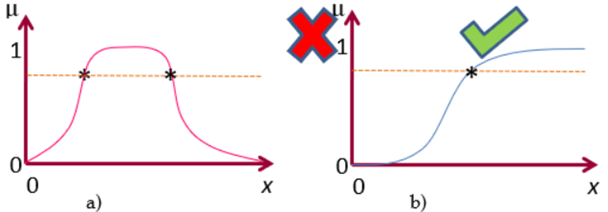

La lógica difusa fue introducida por primera vez en 1965 por el profesor Lotfi Asker Zadeh, profesor de la Universidad de California, Berkeley, EE. UU. En el método Tsukamoto, la implicación de cada regla dio forma a implicaciones "Causa y efecto" / Implicaciones "Entrada - Salida" en las que el antecedente y el consecuente necesitan algo que hacer. Cada regla se representa mediante conjuntos difusos, las funciones de pertenencia son monótonas. Además, la investigación sobre la aplicación del método Tsukamoto (lógica difusa) en un sistema de apoyo a la toma de decisiones para determinar la cantidad de producción de bienes en función de los datos de inventario y el número de solicitudes.

## Desarrollo

### Problema 1

**Instrucciones**

La herramienta **Fuzzy Logic Toolbox (FLT)**, Cuenta con una interfaz de gráfica de diseño de sistemas de inderencia difusos.

Para conecer el uso de esta interfaz se puede consultar la implentación del **problema de la propina **(problema de un sistema con dos entradas y una salida). La implementación es mediante la inferencia tipo Mandani. Para consultar dicha implementación puedes revisar el siguiente enlace: [Build Fuzzy Systems Using Fuzzy Logic Designer](https://www.mathworks.com/help/fuzzy/building-systems-with-fuzzy-logic-toolbox-software.html)

El problema  a desarrollar consisten en hacer uso de la herramienta gráfica para construir un sistema de inferencia difuso tipo Mandani. El problema es una variante del problema de la propina. Las condiciones son las siguientes

- 2 entradas (servicio y comida)

- El universo de discuros de ambas variables lingüisticas es $[0,100]$

- 1 salida (propina)

- El universo de discurso de esta variable lingúistica es [0,15] 

- Cada variable lingúistica dene tener por lo menos cuatro valores lingúisticos. Por lo menos un valor lingúistico debe ser una variación de un primitivo (por ejemplo: muy rica).

- La semantica de cada variable lingüista se deja a su *"experiencia como consumidor"*

- Se tienen que proponer por lo menos cuatro reglas si - entonces, para la inferencia difusa (se tiene que utilizar por lo menos una vez cada conjunto difuso propuesto en su semántica)

En el desarollo se espera el planteamiento del problema a resolver, así como documentar la construcción correspondiente (parecido a lo presentado en el enlace anterior)

**Planteamiento del problema**

Para la solución de este problema se inició  definiendo los posibles valores de las variables lingüisticas *servicio*, *comida *y *propina*. Para la variable *servicio* se consideraron cuatro posibles valores: *muy malo, malo, regular *y* bueno*. Para la variable *comida *se tiene: *mala, regular, buena *y* deliciosa*. Finalmente para la *propina* se tiene: *muy barata, barata, promedio *y* generosa*. 

El ajuste de los parámetros de las funciones de membresía de cada variable se hizo a un criterio propio. Por ejemplo, para la variable servicio se trabajó con funciones gaussianas. Primero se definió la función de membresía* malo*, con el centro de la curva en 35 , ya que se considera que una calificación de 35 en servicio es clasificado como un servicio malo con grado de membresía uno. Posteriormente, se definió la curva para *muy malo*, la cual fue la función de *malo* al cuadrado. Para *regular* se eligió un 60 como centro de la curva y para *bueno* un centro en 80. Los parámetros de las demás funciones de membresía se eligieron bajo el mismo razonamiento y criterio propio.

Posteriormente se buscó crear reglas que describieran de forma eficiente las posibles combinaciones de los valores y respentando las experiencias como consumidor. Las reglas elegidas fueron:

- Si el *servicio* es muy *malo,* entonces la *propina* es *muy* *barata*.

- Si el *servicio *es *bueno* y la *comida* es *deliciosa,* entonces la *propina *es *generosa*.

- Si el *servicio* es *regular* o la *comida* es *regular*, entonces la *propiana* es *promedio*.

- Si el *servicio* es *malo* o la *comida* es *mala*, entonces la *propina* es *barata*.

- Si el *servicio* es *bueno* y la *comida* es *buena*, entonces la *propina* es *generosa*.

Una vez definidas los valores lingüisticos de cada variable y las reglas de inferencia sólo resta implementar el código.

**Implementación**

Al teclear el siguiente código, se abre una ventana como la siguiente.

fuzzyLogicDesigner

Para agregar una variable debemos dar clic en el botón *edit y *seleccionar la opción *input*.

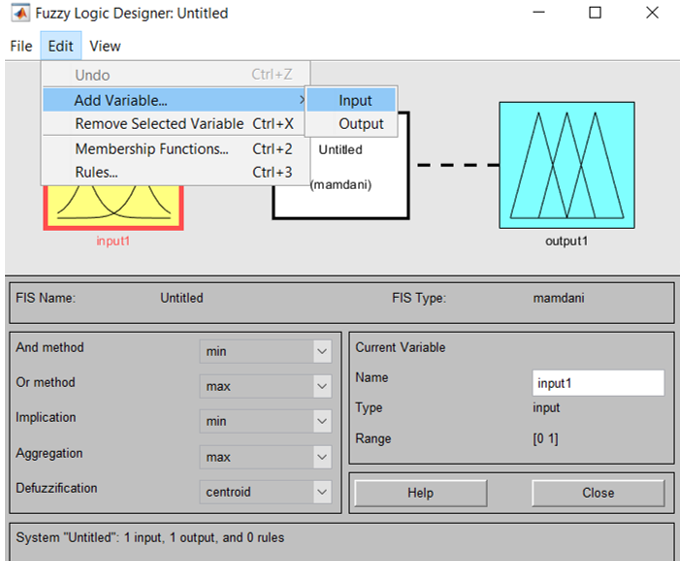

Para cambiar los nombres de las señales de entrada damos clic sobre los recuadros color amarillo y editamos el nombre en el recuadro mostrado a continuación y posteriormente damos enter.

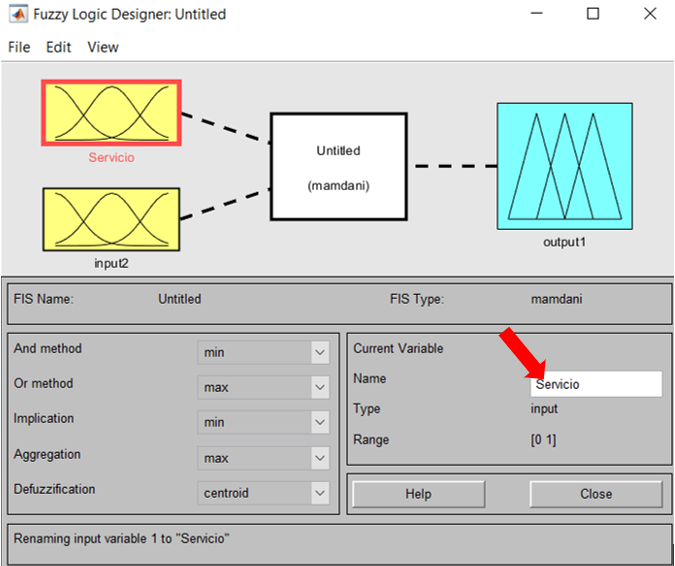

Así modificamos el nombre de la otra entrada a *comida*. Para cambiar el nombre de la salida damos clic en el recuadro azul y modificamos el nombre en el recuadro *name*.

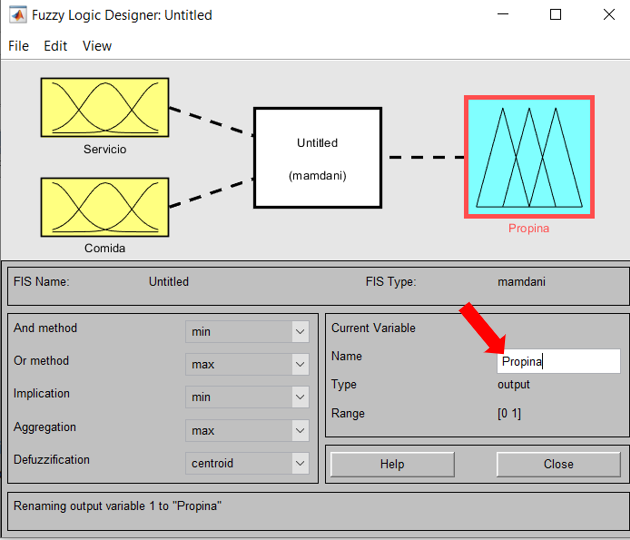

Para agregar funciones de membresía a cada valor lingüistica damos doble clic sobre el recuadro de la variable, se desplegará la siguiente ventana.

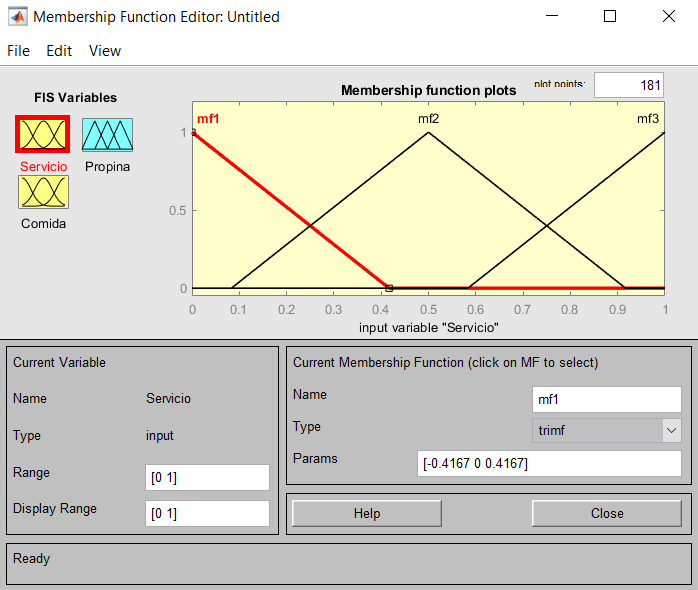

Primero vamos a cambiar el rango en la sección *Range*, por [0 100] en las variables *servicio* y *comida*. En la salida *propina* pondremos el rango [0 15].

Volvemos a dar doble clic sobre la varible *servicio* y seguimos los siguientes pasos para borrar las funciones de membresía que tiene por dafault.

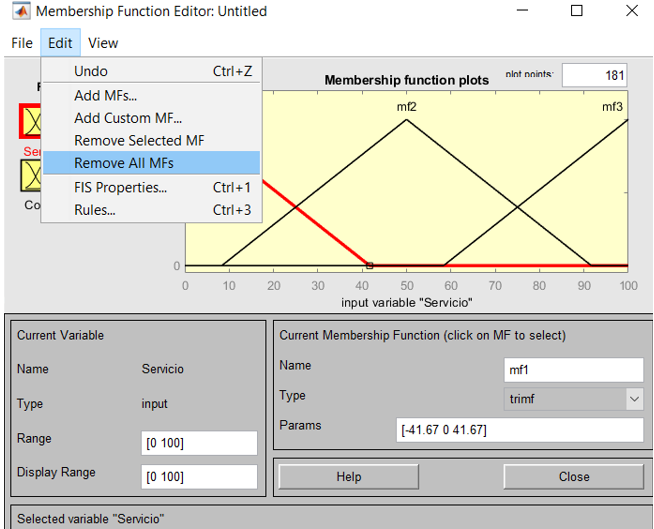

Tras haber borrado las funciones de membresía, vamos a agregar nuevas. En la sección *MF type *elegimos *gaussmf* y en *number* of *MFs* seleccionamos *3*.

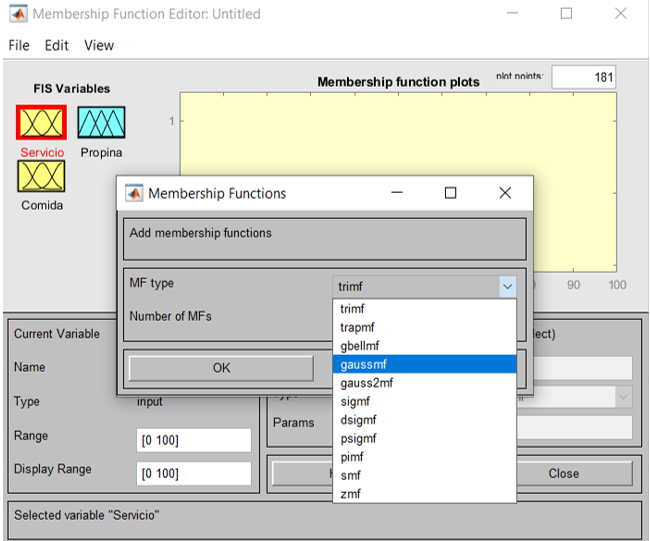

También vamos a agregar una función creada por nosotros mismos, pues se van a usar las valores *muy malo, malo, regular *y* bueno* para la variable lingüistica *servicio*. Entonces, fue necesario crear una función que elevara al cuadrado la función *malo*, para así poder describir el valor *muy malo*.

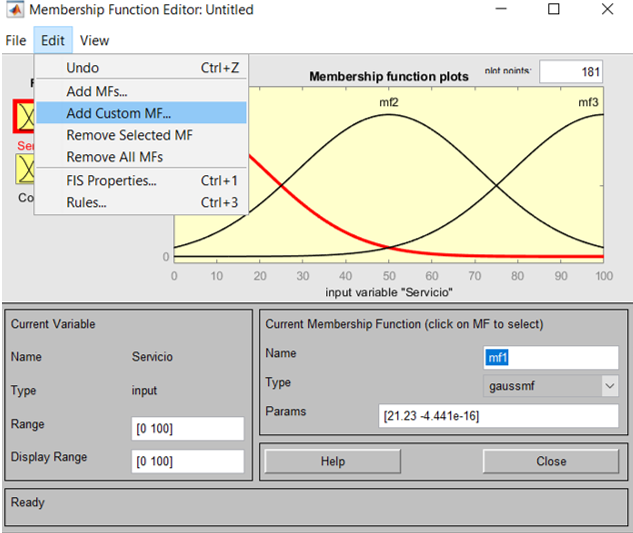

En la ventana que aparece pondremos el nombre de la función de membresía en la sección *MF name*, en la sección* M-file function name* pondremos mRc, el cual es el nombre de la función creada para calcular el cuadrado de la función malo. En la sección parameter list escribimos los parámetros [12,0]. Posteriormente damos clic en *ok*.

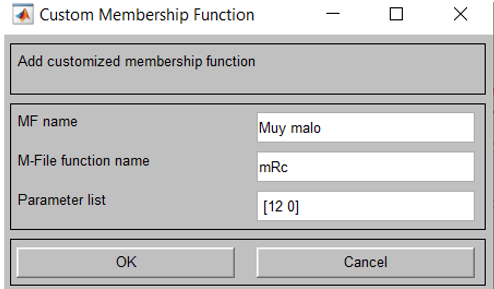

El siguiente paso es editar los nombres y los parámetros de las funciones de membresía que habíamos agregado en pasos anteriores. Para editar las funciones de membresía damos clic sobre la curva que se va a editar. Una de las curvas tendrá como nombre *malo*, con parámetros [12 35].Otra curva se llamará *regular* y tendrá los parámetros [12 60]. Finalmente, la cuarta curva tendrá el nombre *bueno* y tendrá los parámetros [12 80]. Las funciones de membresía resultantes lucen como a continuación. 

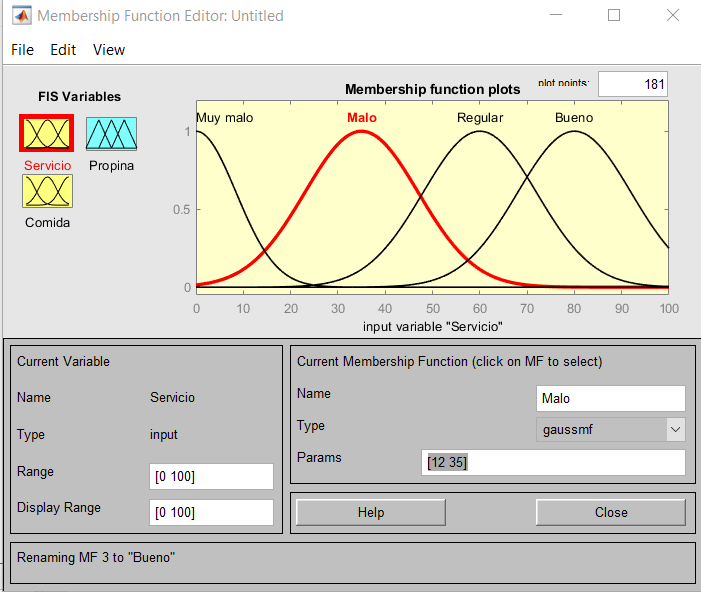

De la misma manera se editarán las funciones de membresía de la variable comida, la cual tendrá cuatro curvas, de tipo *trapmf*.  Las curvas serán *mala* con parámetros  [-10 0 15 45], *regular* con parámetros  [35 40 60 65], *buena* con parámetros  [55 65 80 90] y *deliciosa* con parámetros  [75 90 100 130]. Las funciones de membresía lucen de la siguiente forma.

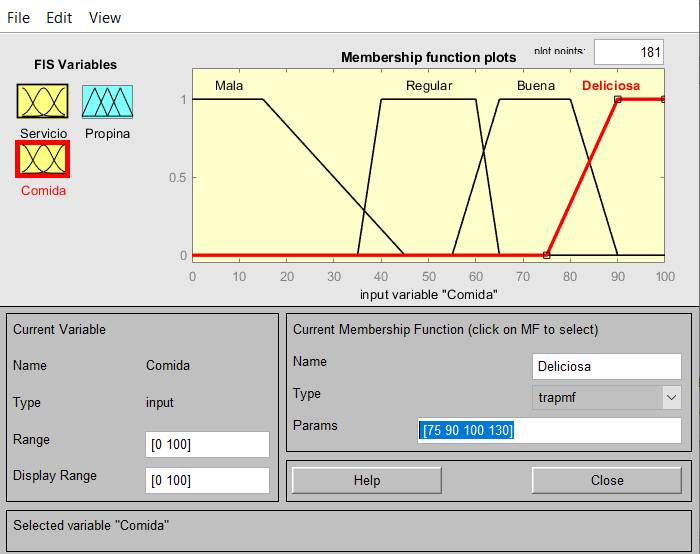

Ahora debemos agregar las funciones de membresía de la variable de salida, se agregarán cuatro curvas tipo *trimf*. Las curvas serán *muy barata* con parámetros  [-5 0 5], *barata *con parámetros  [0 5 10], *promedio* con parámetros  [5 10 15] y *generosa* con parámetros  [10 15 20]. Las funciones de membresía lucen así.

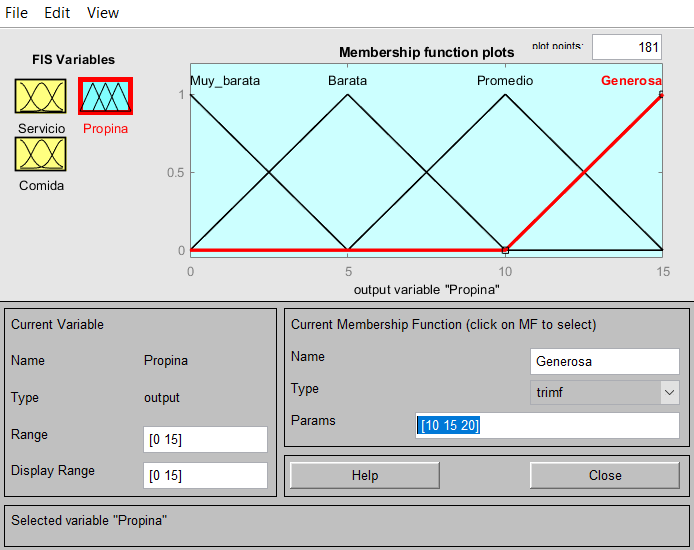

Una vez definidas las variables lingüisticas y sus funciones de membresía se pueden armar las reglas de inferencia difusa. Las fueron definidas de acuerdo a nuestra experiencia como consumidor, las cuales son:

- Si el *servicio* es muy *malo,* entonces la *propina* es *muy* *barata*.

- Si el *servicio *es *bueno* y la *comida* es *deliciosa,* entonces la *propina *es *generosa*.

- Si el *servicio* es *regular* o la *comida* es *regular*, entonces la *propiana* es *promedio*.

- Si el *servicio* es *malo* o la *comida* es *mala*, entonces la *propina* es *barata*.

- Si el *servicio* es *bueno* y la *comida* es *buena*, entonces la *propina* es *generosa*.

Para poder agregar las reglas debemos dar clic en la sección de *edit* y dar clic sobre *rules*.

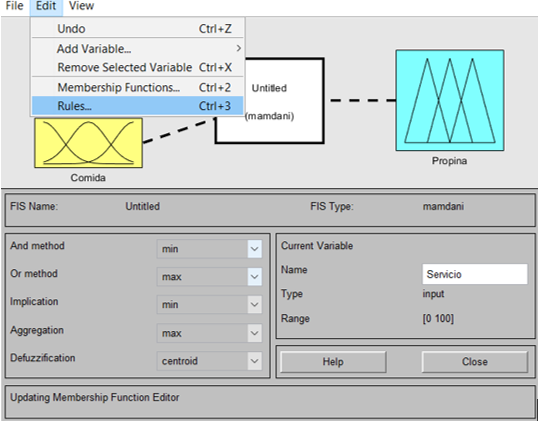

Se abrirá una nueva ventana, en la cual podemos agregar las reglas de inferencia. En la parte media a la izquierda aparecen los valores de las variables lingüisticas y debajo de ellas aparecen los conectores *or* y *and*. También, en la parte media a la derecha aparecen los valores de la variable de salida. Seleccionamos las palabras que describan las reglas que se desean agregar y posteriormente damos clic en *add rule*. Por ejemplo, para agregar la primera regla debemos seleccionar las siguientes palabras.

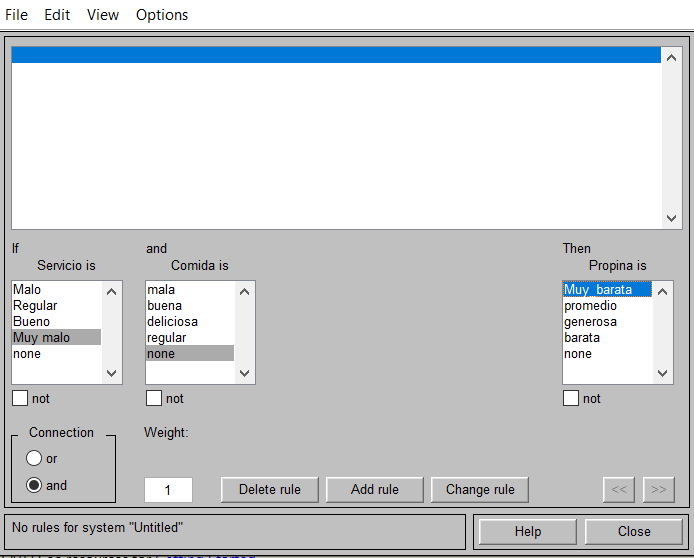

La pestaña con todas las reglas agregadas luce de la siguiente manera.

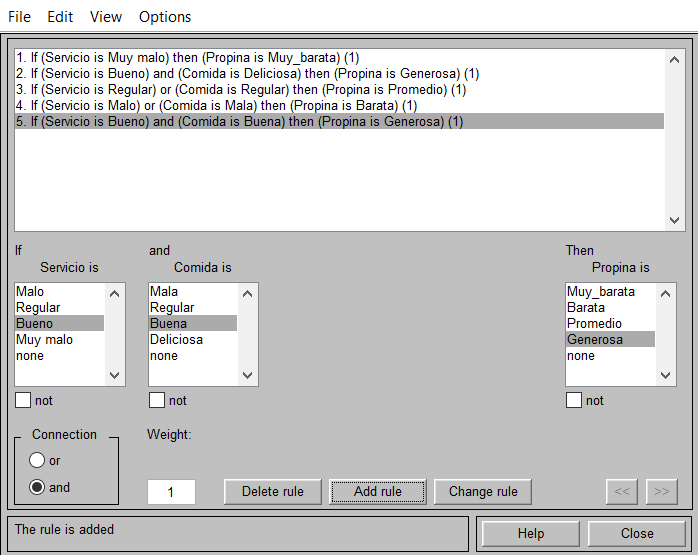

Tras haber agregado todas las reglas debemos exportar el trabajo al workspace, dando clic en *file>>export>>to workspace*. Se abrirá una ventana como la que se muestra a continuación, en la cual debemos escribir el nombre del sistema.

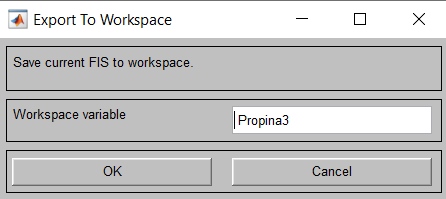

Hecho todo lo anterior podemos ver las reglas de nuestro sistema dando clic en la pestaña *view>>rules*. Se abrirá una nueva ventana que mostrará las gráficas de nuestras 2 variables lingüisticas de entrada y las gráficas de la variable de salida. Desde la sección *input* podemos agregar el valor de las entradas y el programa nos dará la propina adecuada, según las reglas de inferencia.

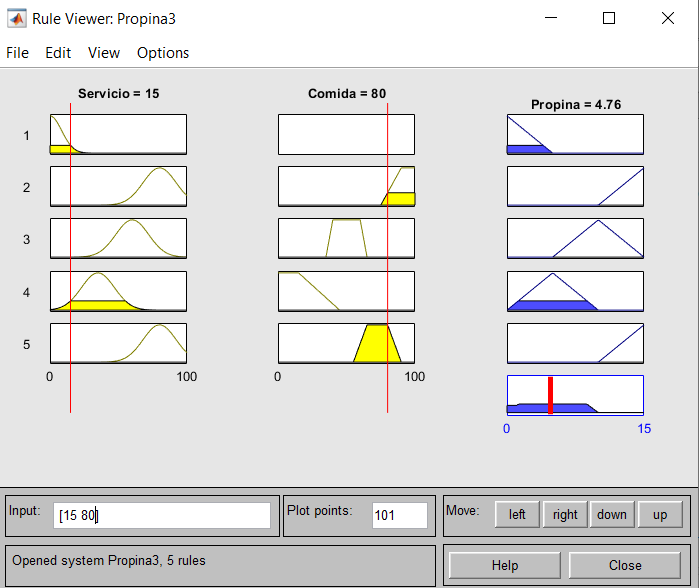

**Preguntas**

**¿Existe una situación donde el problema usual tenga "mal desempeño" al compararlo con tu implementación?**

Sí, aunque de forma general se considera que el programa "tipper" tiene un desempeño bastante eficiente ,la forma de determinar la propina parece ser "promediando" los valores de servicio y comida. En el caso donde se tiene un servicio malo, con calificación  0 y una comida con calificación 10 (la máxima), el programa dice que la propina debería ser del 15%, la cual es una propina promedio(según las funciones de membresía del ejemplo). De acuerdo a nuestro criterio, cuando el servicio en algún restaurante es malo aunque la comida sea muy rica se deja una propina baja por el disgusto ocasionado al consumidor.

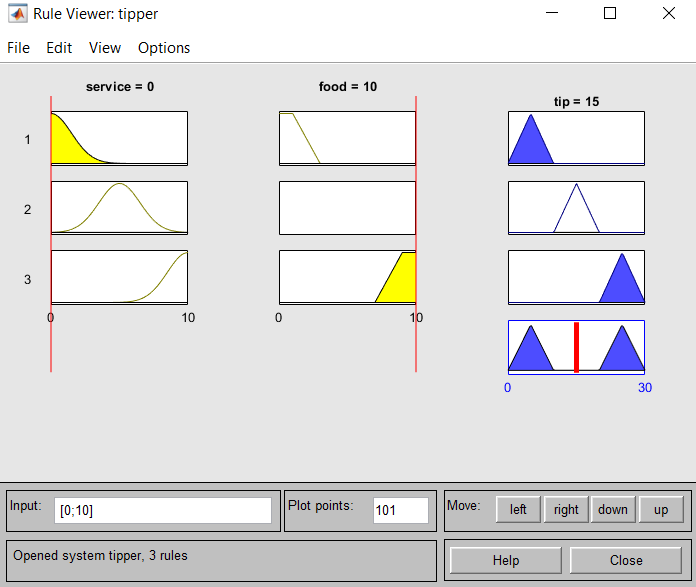

Por otra parte, nuestro programa sí considera esta situación y cuando el servicio obtiene una calificación considerada como muy mala, entonces la propina es muy barata, sin importar la calidad de la comida, pues sentimos que este comportamiento se apega más a la realidad.

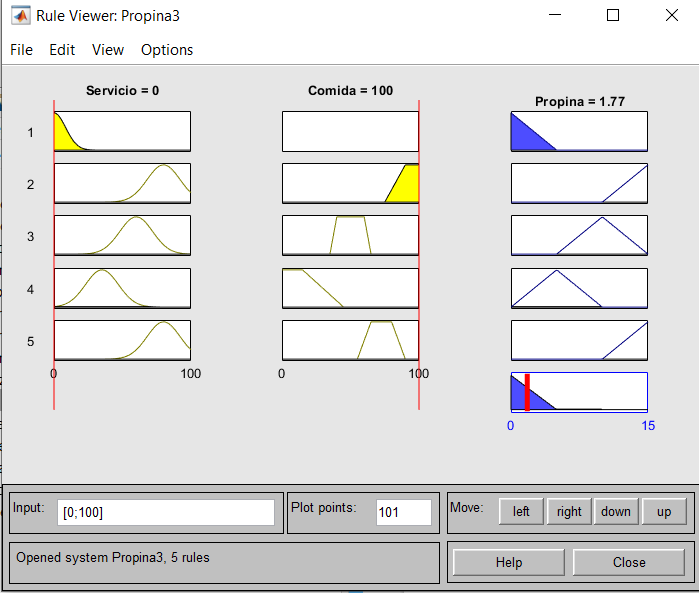

**¿Existe una situación donde el problema usual tenga "mejor desempeño" al compararlo con tu implementación?**

Sí,con el ejemplo "tipper" en el caso donde la comida y el servicio tienen el mayor puntaje posible, también se tiene una propina con el mayor puntaje posible. 

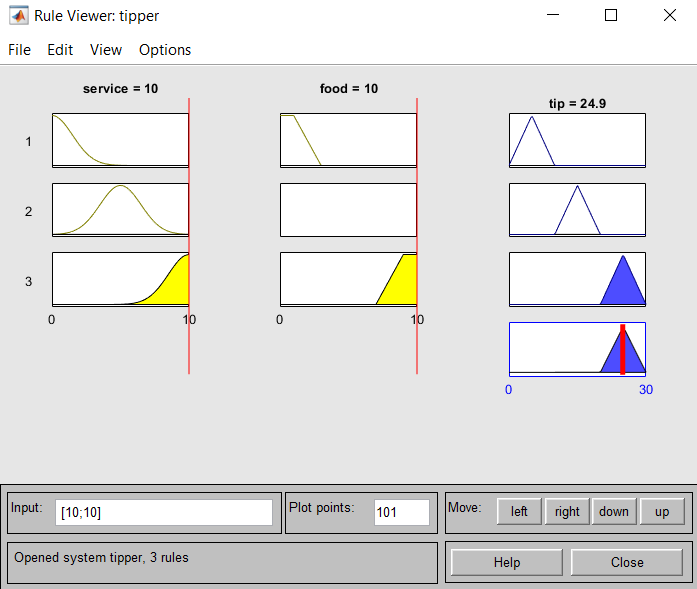

Esto no se logró con nuestra implementación, pues la máxima propina alcanzada cuando el servicio y la comida tienen puntuación de 100 es de 12.7% y se esperaba que se obtuviera una propina de 15%. 

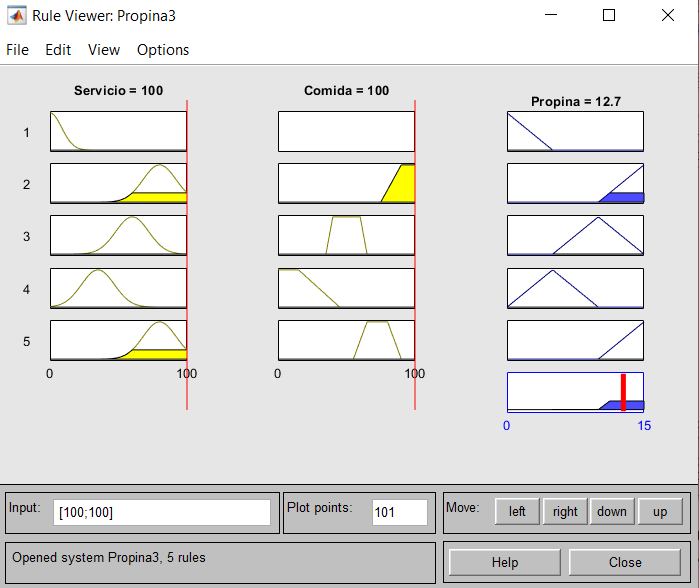

### Problema 2.

La implementación en Simulink de un FIS para aplicaciones de control, se realiza principalmente con los siguientes bloques:

- [Fuzzy Logic Controller](https://www.mathworks.com/help/fuzzy/fuzzylogiccontroller.html) (FLC)

- [Fuzzy Logic Controller with Ruleviewer](https://www.mathworks.com/help/fuzzy/fuzzylogiccontrollerwithruleviewer.html) (FLCR)

El funcionamiento de los bloques sigue el principio de Simulink, se conectan las entradas, se procesan y se generan las salidas. En cada bloque basta indicar el nombre del sistema FIS. Este puede ser construido con el fuzzyLogicDesigner y exportado al workspace. También puede ser construido mediante alguna de las posibles alternativas de código.

Existen dos diferencias principales entre ambos bloques. El primero se puede asociar a diferentes sistemas a inferencia, mientras el segundo, solo puede ser asociado a un FIS tipo Mandami o Sugeno, pero con la ayuda visual de RuleViewer (descrito en el enlace del problema 1).

Para explorar la implementación de los FIS en Simulink. Se trabajará con el control de nivel de agua en un tanque.

Se tiene la siguiente implementación en Simulink.

open_system('sltank')

La instrucción anterior abre el ejemplo antes mencionado. En particular se genera en el workspace la variable tank tipo *mamfis *(Sistema de inferencia difuso tipo Mamdani).

tank

Este FIS es el que se encuentra asociado al bloque FLC. Puedes explorar esta simulación de acuerdo a lo descrito en el siguiente enlace: [Water Level Control in a Tank](https://www.mathworks.com/help/fuzzy/water-level-control-in-a-tank.html). Puedes explorar el FIS de varias maneras, para hacerlo con la app

fuzzyLogicDesigner(tank)

Con apoyo de lo anterior, contesta lo siguiente:

**2.1 ¿Cuántas variables lingüísticas se tienen?**

Se tienen 3 variables lingüísticas, dos entradas y una salida. 

Las primera entrada es el error de nivel de agua, la variable lingüística llamada como: ***nivel***. Esta variable tiene 3 conjuntos difusos llamados: alto, bueno, bajo.

La segunda entrada es la tasa de cambio de nivel de agua, la variable lingüística llamada como: ***tasa de cambio***. Esta variable tiene 3 conjuntos difusos llamados: negativa, ninguna, positiva.

La salida  del sistema difuso es la velocidad de apertura o cierre de la válvula de control. La variable lingüística es ***válvula***. Esta variable tiene 5 conjuntos difusos llamados: cerrar_rápido, cerrar_lento, sin_cambio, abrir_lento, abrir_rápido.

**2.2 ¿Cuál es el universo de discurso de cada una?**

El univero de discurso de la variable lingüística ***nivel*** es:

[-1.1,1.1]. Esto se puede apreciar en las especificaciones de la gráfica de esta variable.

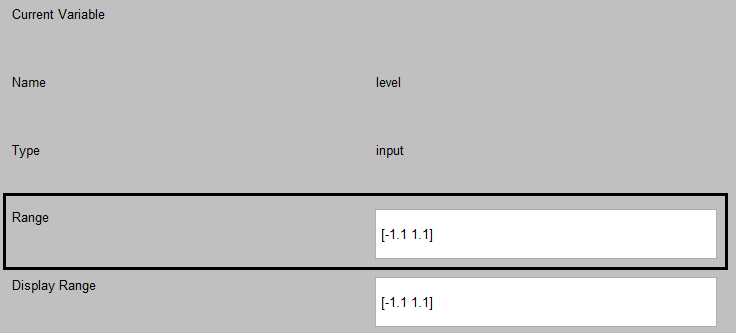

El universo de discurso de la variable lingüística ***tasa de cambio ***es:

[-0.35,0.35]. Esto se puede apreciar en las especificaciones de la gráfica de esta variable.

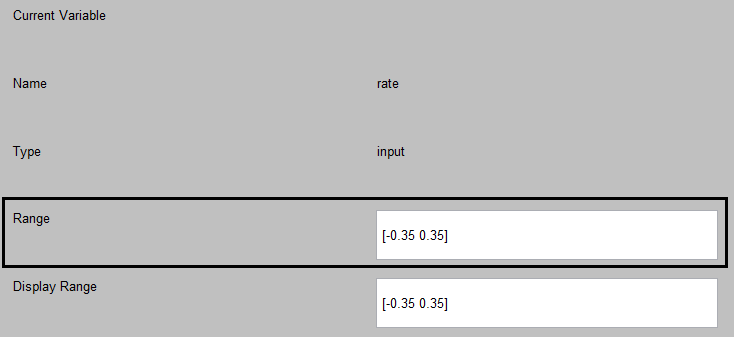

El universo de discurso de la variable lingüística ***válvula ***es:

[-1,1]. Esto se puede apreciar en las especificaciones de la gráfica de esta variable.

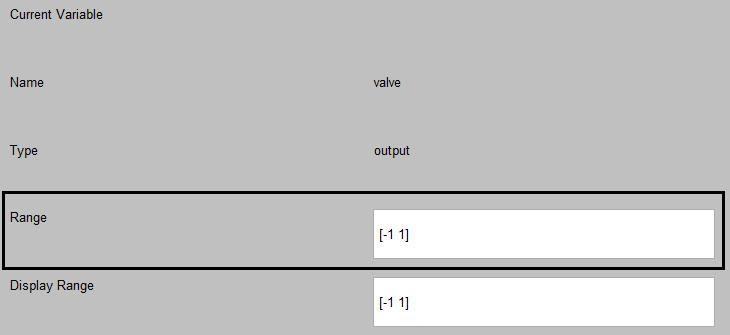

**2.3 Grafica los conjuntos difusos de cada variable lingüistica.**

La gráfica de los conjuntos difusos de cada variable lingüística se muestra a continuación, primero se realizó un código que las grafica, y después se graficaron esos conjuntos con la ayuda gráfica de fuzzyLogicDesigner().

fis = mamfis('Name','Tank'); % Nombre del mamdani
fis = addInput(fis,[-1.1 1.1],'Name','nivel'); % Primera entrada: nivel
fis = addMF(fis,"nivel","gaussmf",[0.3 -1],'Name', 'alto');
fis = addMF(fis,"nivel","gaussmf",[0.3 0],'Name', 'bueno');
fis = addMF(fis,"nivel","gaussmf",[0.3 1],'Name', 'bajo');

fis = addInput(fis,[-0.35 0.35],'Name','tasa de cambio'); % Segunda entrada: tasa de cambio
fis = addMF(fis,"tasa de cambio","gaussmf",[0.03 -0.1],'Name', 'negativa');
fis = addMF(fis,"tasa de cambio","gaussmf",[0.03 0],'Name', 'ninguna');
fis = addMF(fis,"tasa de cambio","gaussmf",[0.03 0.1],'Name', 'positiva');

fis = addOutput(fis,[-1 1],'Name','valvula'); % Salida: valvula
fis = addMF(fis,"valvula","trimf",[-1 -0.9 -0.8],'Name', 'cerrar_rapido');
fis = addMF(fis,"valvula","trimf",[-0.6 -0.5 -0.4],'Name', 'cerrar_lento');
fis = addMF(fis,"valvula","trimf",[-0.1 0 0.1],'Name', 'sin_cambio');
fis = addMF(fis,"valvula","trimf",[0.2 0.3 0.4],'Name', 'abrir_lento');
fis = addMF(fis,"valvula","trimf",[0.8 0.9 1],'Name', 'abrir_rapido');

figure
plotmf(fis,'input',1) % Grafica de nivel
figure
plotmf(fis,'input',2) % Grafica de tasa de cambio
figure
plotmf(fis,'output',1) % Grafica de valvula

A continuación se muestran las gráficas realizadas de manera gráfica con fuzzyLogicDesigner().

La variable lingüística ***nivel*** con los conjuntos difusos **bajo, bueno, alto.**

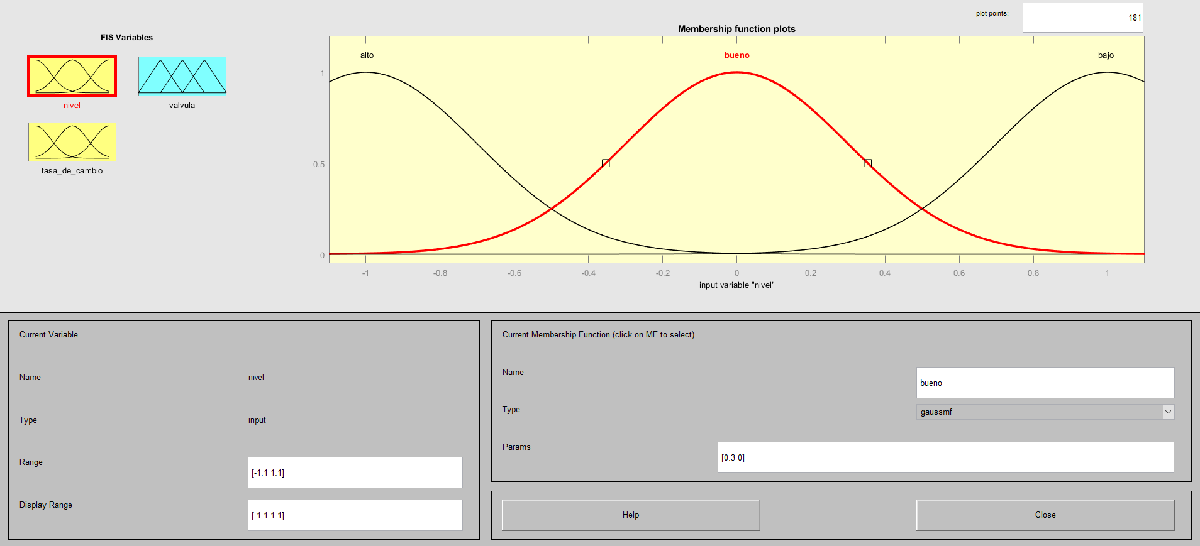

La variable lingüística ***tasa de cambio*** con los conjuntos difusos **negativa, ninguna, positiva.**

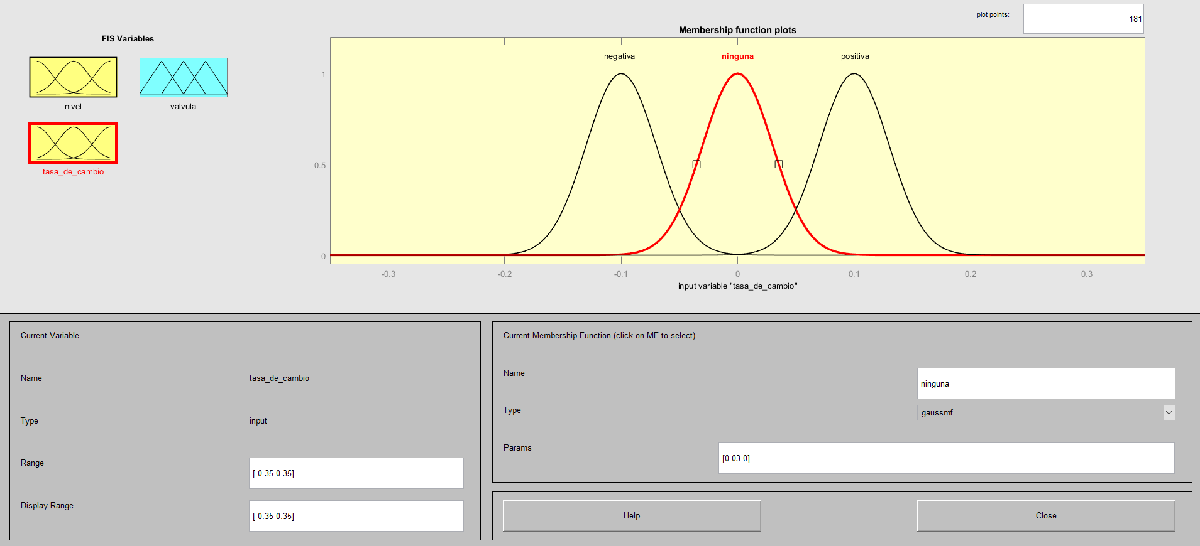

La variable lingüística ***válvula*** con los conjuntos difusos **cerrar_rapido, cerrar_lento, sin_cambio, abrir_lento, abrir_rapido.**

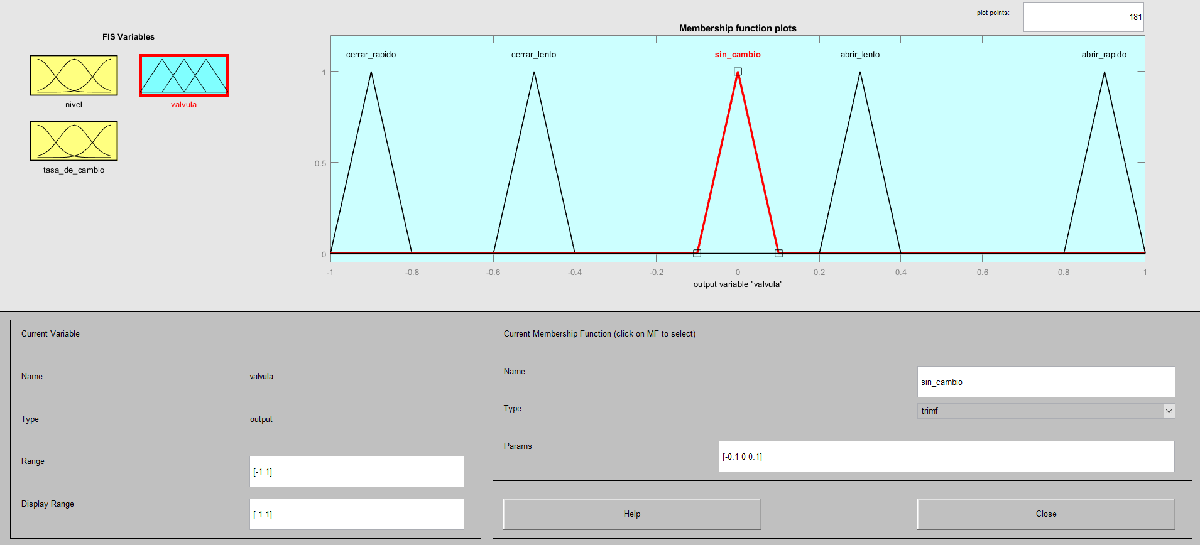

**2.4 Muestra las reglas de inferencia difusa utilizadas.**

Las reglas de inferencia difusa utilizadas son 5, tres reglas en donde sólo se ocupa la variable ***nivel*** como antecedente, y dos reglas donde se usan tanto ***nivel*** como ***tasa de cambio*** como antecedente.

- Si ***nivel*** es **bueno**, entonces ***válvula*** es **sin_cambio.**

- Si ***nivel*** es **bajo**, entones ***válvula*** es **abrir_rápido**.

- Si ***nivel*** es **alto**, entonces ***válvula*** es **cerrar_rápido.**

- Si ***nivel*** es **buen**o y ***tasa de cambio*** es **positiva**, entonces ***válvula*** es **cerrar_lento.**

- Si ***nivel*** es **bueno**, y ***tasa de cambio*** es **negativa**, entonces ***válvula*** es **abrir_lento.**

**2.5 Explica en que consiste la implementación del sistema (una descripción general de todos los bloques) en especial los bloques de visualización, así como la simulación mostrada.  **

El diagrama de bloques del sistema es el que se muestra a continuación:

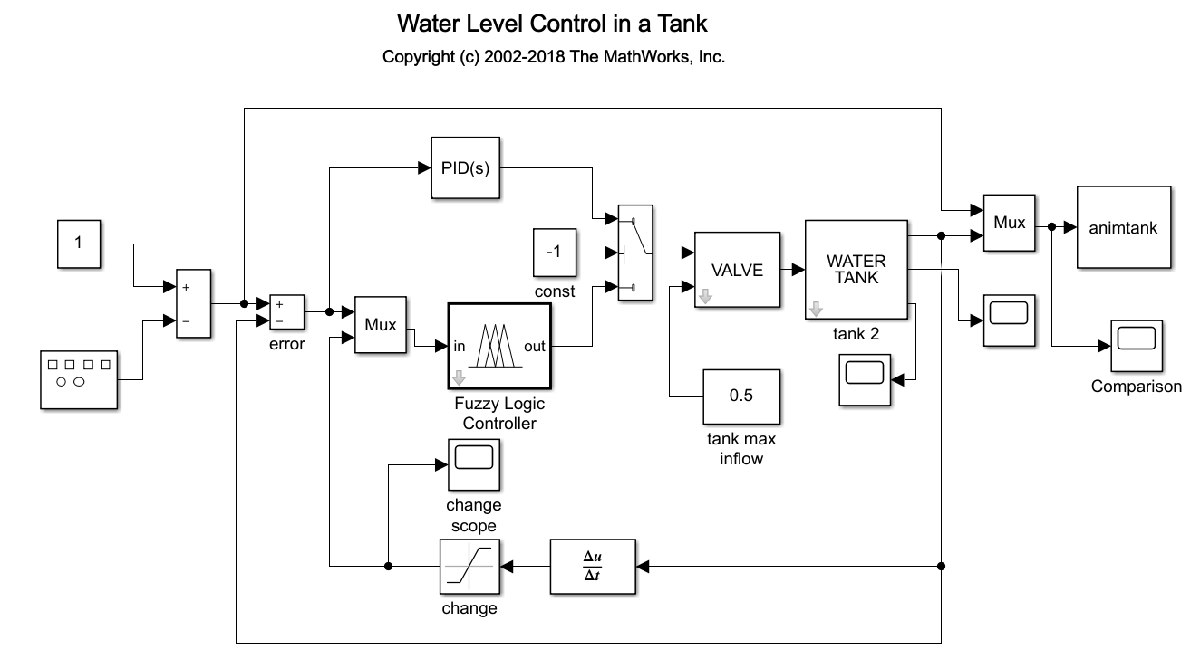

Comenzaremos con la entrada del sistema en donde bloque de generador de señales se encuentra generando para este caso una onda cuadrada. No obstante, como amplitud tiene un valor de 0.5, pero para que que la oscilación de la señal cuadrada sea en torno al número uno, se usa el bloque constante con valor de 1, como se observa en la figura pasada. Y se usa un bloque de suma para hacer la diferencia entre el bloque constante 1 con la señal cuadrada,  de este modo la señal de entrada oscile entre 0.5 y 1.5.

Esta señal cuadrada entrante actúa como el valor deseado. Ahora bien, la otra señal que entra para hacer la diferencia y obtener el error, es precisamente la señal de salida del sistema (nivel de agua) y se conecta con el bloque que tiene como nombre "error". De esta manera, se hace la diferencia entre la señal cuadrada deseada y la señal real que se está obteniendo del sistema. 

La señal de error (que es la diferencia de las dos) se introduce al bloque multiplexor que como se aprecia tiene dos entrada y una salida, siendo esta señal de error una de estas entradas. La segunda entrada es la tasa de cambio de la salida que se obtiene de diferenciar el nivel de la salida del sistema, no obstante, tiene un bloque con el nombre "change" que lo que provoca es limitar dicha señal a unos valores de saturación inferior y superior, siendo -0.1 y 0.1 respectivamente, es decir, no permitir que se pasen de dichos valores, incluso hay un scope (change scope) para poder ver esta señal diferenciada.  Una vez se encuentre limitada, se introduce en el multiplexor que va a superpone a ambas señales mencionadas para transmitirla al siguiente bloque en una sola salida.

La salida del multiplexor va hacia el bloque del controlador lógico difuso. En este controlador se encuentra el archivo en donde se encuentra todo el proceso de inferencia difusa como todas las reglas mencionadas en el punto anterior, de tal manera que dependiendo de lo que ocurra en las entradas sabrá responder de cierta manera para la salida.

Hasta este punto no se había mencionado nada sobre el bloque del controlador PID, pero hablando al respecto, este controlador se usa como una alternativa al controlador lógico difuso, solamente que tiene una respuesta menos favorable que el del lógico difuso. Como se observa en la figura, el PID recibe como entrada la señal de error. Observando a detalle el bloque del PID se muestra que no está haciendo uso de la I, es decir, es un controlador PD con P = 2 y D = 1. El controlador PD se utiliza principalmente para mejorar la respuesta transitoria del sistema de control. La acción del controlador PD tabmbién es conocidad como control de velocidad, y su efecto inmediato es que la magniud de la salida del controlador es proporcional a la velocidad de cambio de la señal de error. La D por sí sola responde a la velocidad de cambio del error y produce una correción significativa antes de que la magnitud del error se vuelva muy grande. La acción de control del PD se define mediante:


$$u(t) = K_pe(t)+K_pT_d\frac{de(t)}{dt}$$


El resultado de ese controlador se muestra cuando se describa la salida del sistema. Entonces con ambos controladores podemos elegir cuál usar para este sistema mediante el bloque switch. Este bloque switch tiene 3 entradas, la primera y la tercera son señales que salen de ambos controladores, y la de en medio es una constante que es la que decidirá cuál controlador usar, si la constante tiene un valor igual o mayor a 0, se estará haciendo uso del controlador PID, si pasa lo contrario, se hará uso del controlador lógico difuso. Para este caso de explicación y conforme a la imagen, nos percatamos que se está haciendo uso del controlador lógico difuso.

Entonces, la señal que sale del bloque del controlador difuso, entra a un bloque llamado "valve" que es un subsistema. Este subsistema tiene dos entrada, una para la señal que viene del controlador y la otra señal es para un bloque constante con un valor de  0.5 que lo que hace es establecer la entrada máxima del tanque. 

Este subsistema se muestra a continuación:

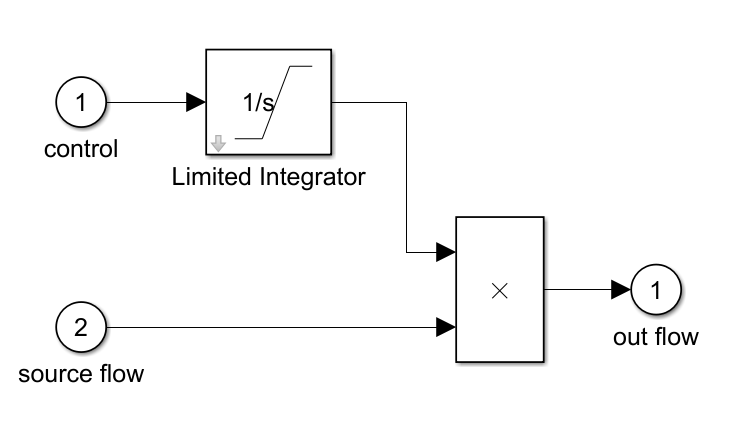

Como se observa de la imagen anterior, tenemos dos entradas, que efectivamente corresponden a las mencionadas previamente que son la salida del controlador y una constante, y podemos apreciar que ambas señales se multiplican no sin antes aplicarle una integración limitada a la señal que sale del controlador mediante el bloque "Limited integrator" que es otro subsistema y se muestra ahora:

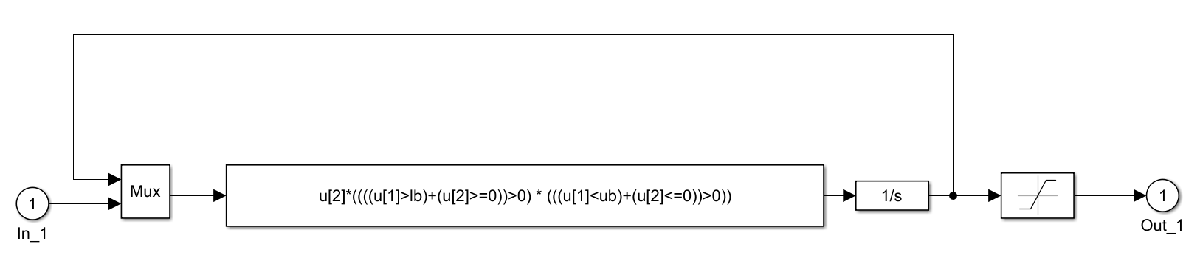

El bloque Mux va a combinar las señales y que van a pasar por el bloque "Fcn" que es una función de la forma que se muestra en el bloque. Una vez que pasa por esa función, la salida pasa por un integrador con una condición inicial que se le coloca al bloque del subsistema. Cuando la señal se haya integrado pasa por un bloque de saturación que limita la integración a partir de un límite inferior y superior que igualmente se introducen en el bloque del subsistema, resultando así la señal integrada y limitada.

Por tanto, en el subsistema "valve", la válvula multiplica la señal de control por el caudal máximo del tanque que como vemos tenía el valor de 0.5 , de modo que se realiza así la acción de control.

La señal que sale del bloque "valve" entra a otro bloque que es otro subsistema llamado "water tank" y que su diagrama de bloques se muestra a continuación: 

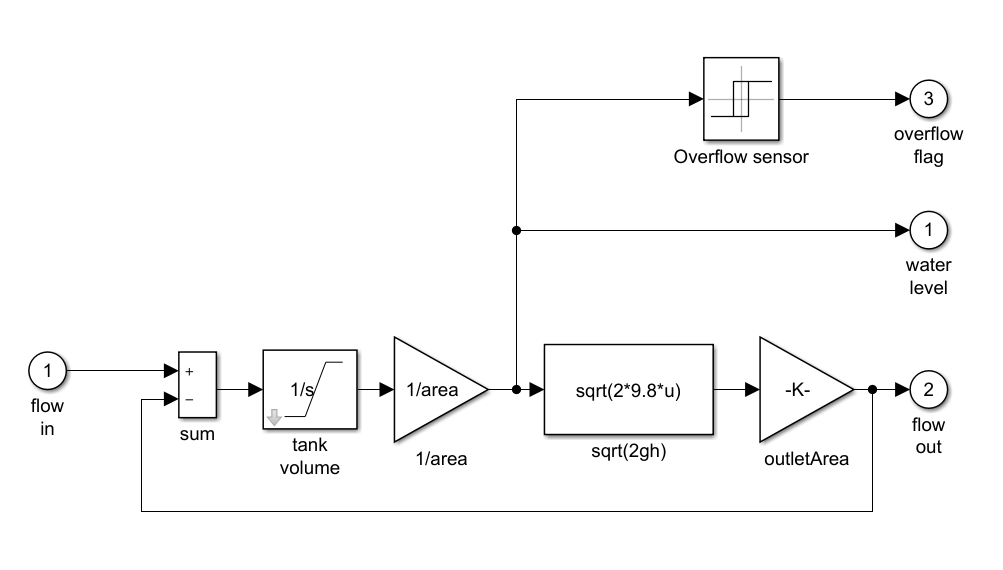

En base a la figura del subsistema "WaterTank" el flujo de salida del sistema se obtiene mediante la fórmula $flowOut = outletArea* \sqrt(2gu)$ donde *g* es la gravedad y *u* es el nivel de agua del tanque, y esa *u* es precisamente la entrada al bloque $sqrt(2gh)$. Y que además esa *u* es la primera señal que se ha mencionado que sale de este subsistema que es el nivel de agua del tanque, que vemos que sufre dos cambios extras para tener las otras dos salidas: para la segunda salida de este sistema sufre el cambio previamente mencionado para obtener el $flowOut$ y otro que pasa por el bloque llamado "overflow sensor" para obtener la señal de desbordamiento.

Este subsistema "WaterTank" tiene ciertos parámetros para que funcione correctamente como lo es la altura del tanque *(ht)*, el área inferior, la sección del tubo de salida, entre otros. 

Además dentro de este subsistema existe otro llamado "tank volume" que realiza la función de un integrador limitado como ya se vio para el subsistema "valve", y que evidentemente necesita parametros que sirven como límites superiores e inferiores y una condición inicial. De hecho, es el mismo subsistema solamente que estos valores son diferentes para cada subsistema.

Al pasar por este bloque de "tank volume" el resultado se multiplica por un factor $\frac{1}{Area}$ debido al bloque de ganancia. Esta multiplicación nos arroja el nivel de agua en el tanque. Y este es la *u* que se ha estado mencionado antes.

 La salida de este subsistema son 3 señales: el nivel de agua, el flujo de salida y la señal de desbordamiento. La primer señal que es el nivel de agua se va a un multiplexor que también recibe otra entrada que es la señal deseada, de tal modo que lo que sale de este multiplexor se puede graficar y como aparece en el nombre del scope (del diagrama de bloques general) se puede hacer una comparación entre la señal deseada y el nivel del agua que se obtiene del sistema. Esta misma primer señal es la que se mencionó al inicio que es la señal real y que se hace la diferencia con la señal ideal o deseada para obtener así la señal de error. Este señal también es la que se mencionó al inició que se hace la diferencial para obtener la tasa de cambio y entrar así al multiplexor para ser superpuesta con la señal de error.

La segunda señal que sale del bloque "water tank"  que es el flujo de salida se va a un scope y convierte el término $outletArea* \sqrt(2gu)$al nivel del agua en un volumen sobre tiempo, o bien, el caudal de salida.

La tercera señal que es la señal de desbordamiento va a otro scope e indica cuándo se ha superado el nivel.

Finalmente, el bloque S-function que en la figura tiene el nombre "animtank".  Permite ver la fluctuación del nivel del tanque mientra se está ejecutando la simulación, que se explicará en la parte final.

**Bloques de visualización**

Para los bloques de visualización se comenzará hablando primero con la configuración para el controlador lógico difuso y posterior para el controlador PID.

- **Usando controlador lógico difuso**

**Scope change**

Como se mencionó, la salida del nivel de agua en una parte del diagrama de bloques se limita mediante un limited integrator para que su rango de la función sólo se mantenga entre [-0.1, 0.1], es por ello que en este scope la gráfica tenga esos límites. Este scope representa la tasa de cambio del nivel del agua.

Podemos entender que cuando esta gráfica se encuentra en 0, el nivel del agua se encuentra estable ya se cuando la señal cuadrada de entrada se encuentra en 0.5 o en 1.5. Luego, podemos ver cómo el nivel de agua cambio de forma rápida debido a esa pendiente grande cuando cambia de 0 a 0.1, y ya cuando se encuentra más cerca del nivel deseado la tasa de cambio se reduce se forma más lenta hasta que se estabiliza, es decir, cuando se vuelve a tener el valor de 0 en este scope. Todo esto regulado con las 5 reglas del controlador.

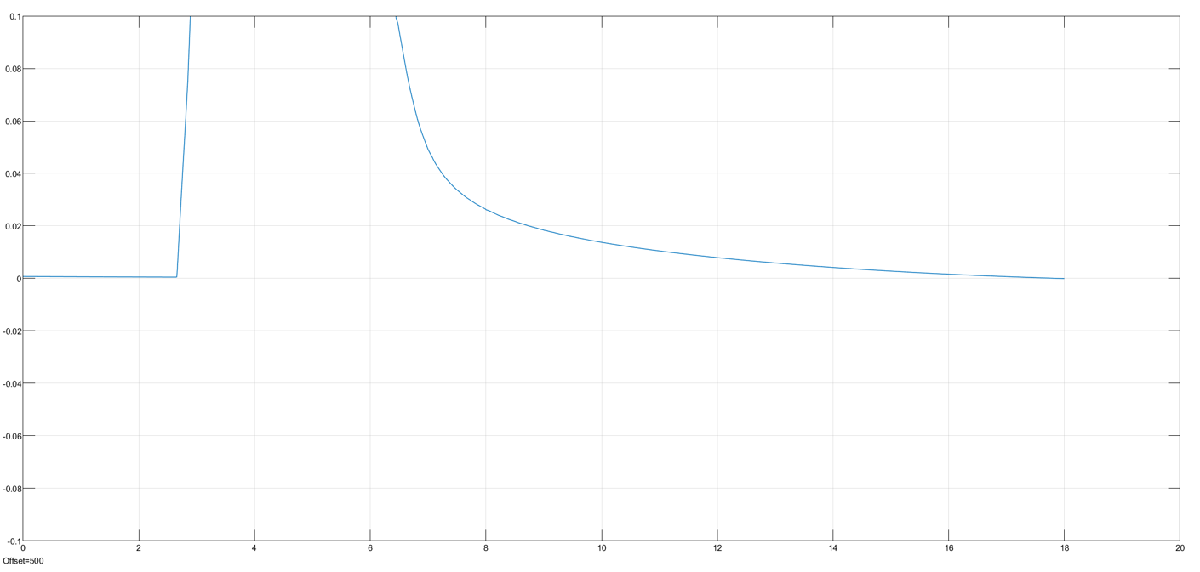

Para la siguiente parte de la gráfica es el mismo proceso, solamente que la de arriba es para cuando se quiere alcanzar el 1.5, y esta de abajo es para cuando se quiere alcanzar el 0.5 debido a la señal cuadrada.

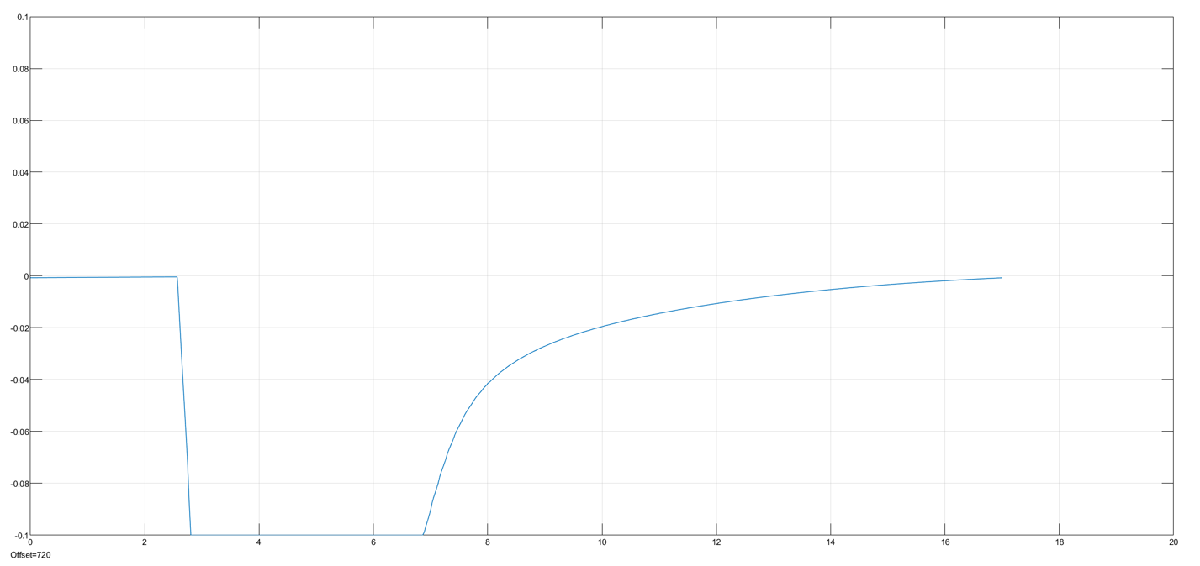

**Primera salida del subsistema water tank**

La primera salida del susistema water tank representa el nivel de agua y está regulado por las reglas del controlador. En la siguiente figura se muestra en color azul la señal cuadrada de entrada y en color rojo la señal de salida del sistema. Lo ideal en este caso sería que la señal roja se pareciera lo más posible a la azul, lo cual no ocurre, no obstante, el resultado es muy bueno. Debido a que a partir de t = 10 para el primer semiciclo la señal es prácticamente igual a la entrada, lo cual el error al inicio es pequeño y la respuesta del sistema para lograr su estabilizar en muy rápida, y podemos ver que no ocurren oscilaciones destacadas para lograr dicha estabilidad. Entonces con este controlador lógico difuso, la respuesta es rápida y con gran estabiidad.

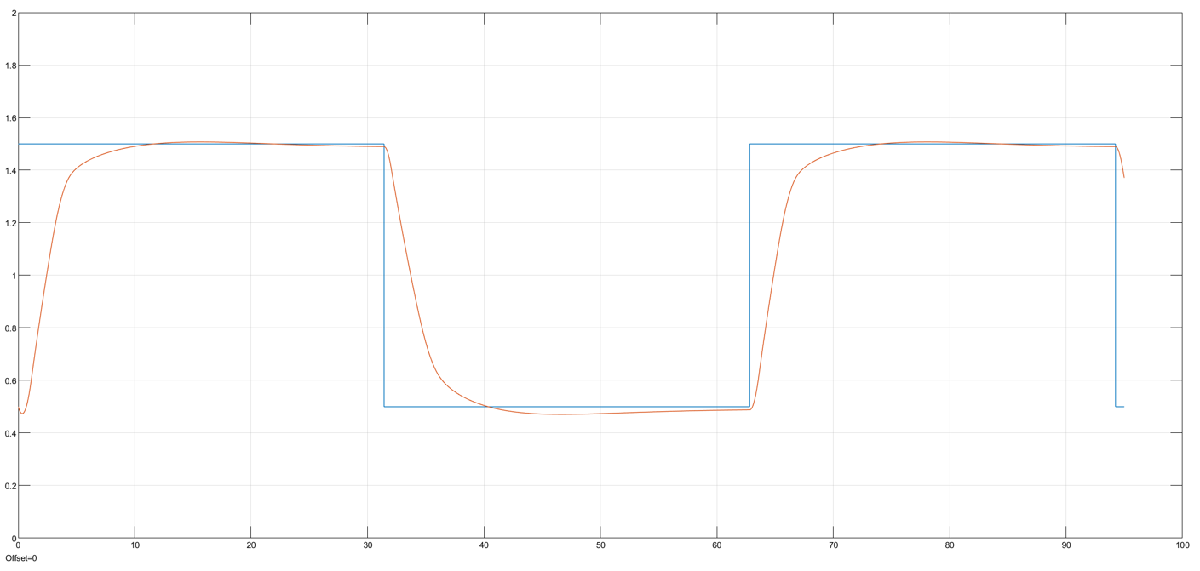

**Segunda salida del subsistema water tank**

La segunda salida del subsistema water tank lo que representa como se ha mencionado es el caudal del sistema, es decir, la cantidad de volumen de agua que sale en determinado tiempo. En la gráfica de abajo, cuando el caudal aumenta de valor es precisamente cuando el nivel del agua del tanque está queriendo alcanzar la nivel más alto de acuerdo a la señal de entrada, y que tiene sentido ya que la fórmula $flowOut = outletArea* \sqrt(2gu)$ da un valor mayor cuando $u$ es mayor, siendo $u$ el nivel de agua. En cambio, cuando el nivel de agua baja debido a que la señal cuadrada va a su valor mínimo de 0.5, este flujo de salida también baja debido a que $u$ es menor. Es así como esta gráfica se encuentra oscilando, aumentando su valor cuando hay mayor nivel de agua, y disminuyendo su valor cuando el nivel de agua es menor.

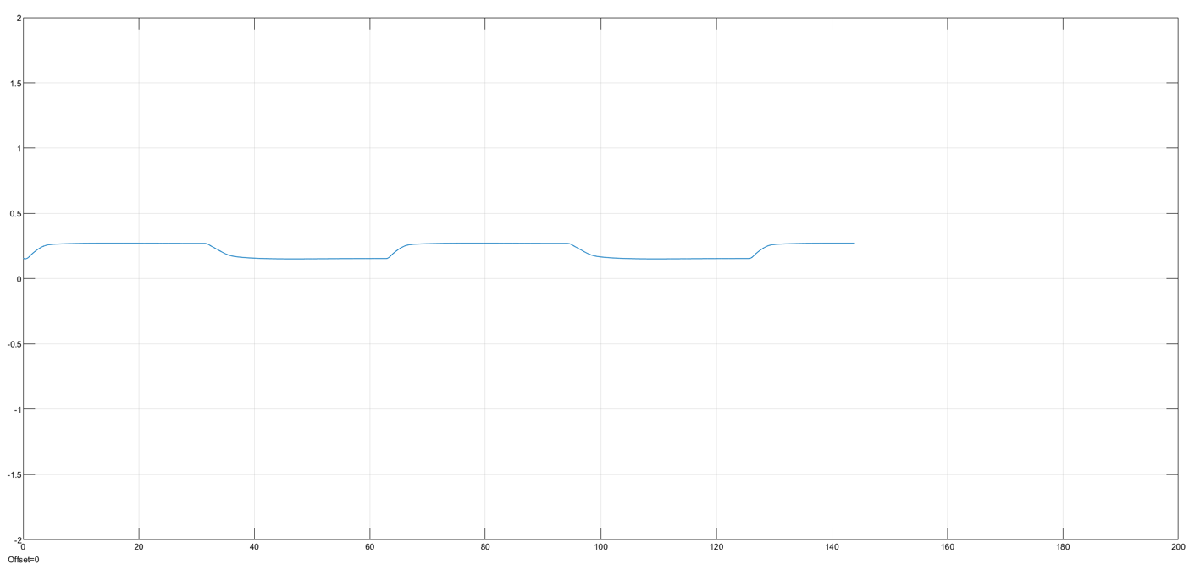

**Tercera salida del subsistema water tank**

La tercera salida de este subsistema se relaciona con que al nivel del agua se introduce a un bloque llamado relay y lo que pasa es que este bloque conmuta entre dos valores especificados. Si este bloque esta encendido, va a permanecer de esa manera hasta que la entrada (nivel del agua) caiga por debajo de un parámetro llamado punto de desconexión. Y de igual la manera lo contrario, si el bloque está apagado, permanecerá así hasta que la entrada supere el valor de un parámetro llamado punto de conexión. De acuerdo al sistema, el valor de salida cuando esta "on" es el valor de 1, mientras que si esta "off" el valor de salida es 0. Para este sistema, cuando se simuló, siempre mostraba el valor de 0. Esto se muestra en la siguiente gráfica:

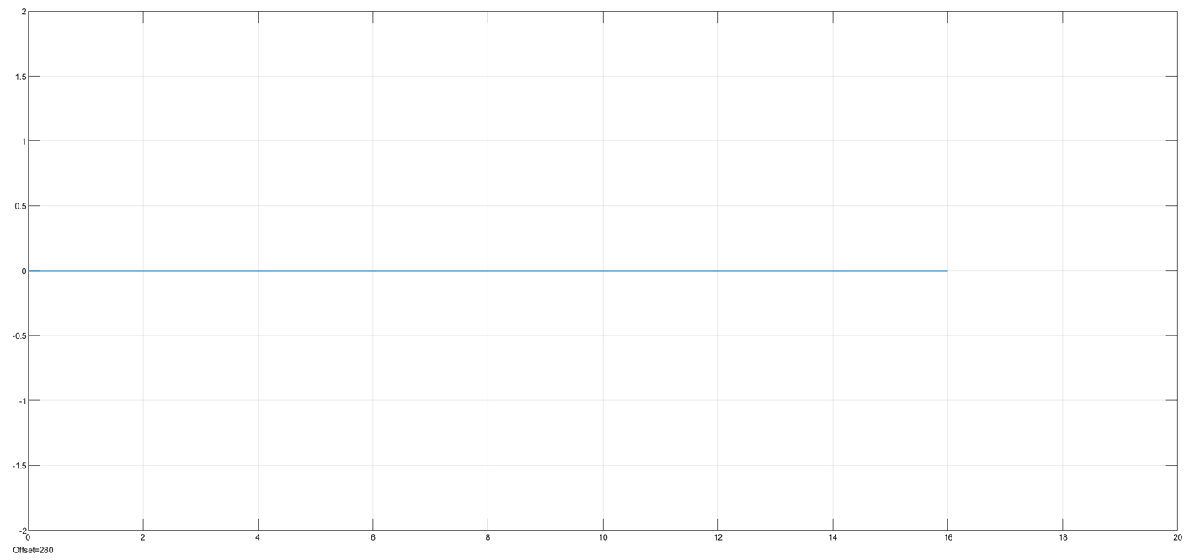

- **Usando controlador PID**

Este sistema también puede ser controlado mediante un controlador PID, donde para este caso solamente se usó PD, con  P = 2 y D = 1. El resultado fue el siguiente:

**Change scope**

Este scope lo que nos muestra es la tasa de cambio del nivel del agua, y donde el valor de 0 representa que o existe ningún cambio en el nivel de agua. Cuando la señal cuadrada hace un cambio al valor de 1.5, esta gráfica tiende inmediantamente a 0.1 ya que es el valor límite que se le estableció, y conforme se va llegando al nivel deseado, esta tasa de cambio va disminuyendo su valor, no obstante, la respuesta aquí es peor que con el controlador lógico difuso, ya que en este existen oscilaciones más pronunciadas cuando quiere tender al valor de 0, es decir, para llegar al valor deseado, oscila alrededor de dicho valor para después estabilizar, contrario a lo que pasaba antes, ya que en el controlador pasado solamente disminuía la velocidad y poco a poco llegaba al nivel deseado sin pasarse de dicho nivel. 

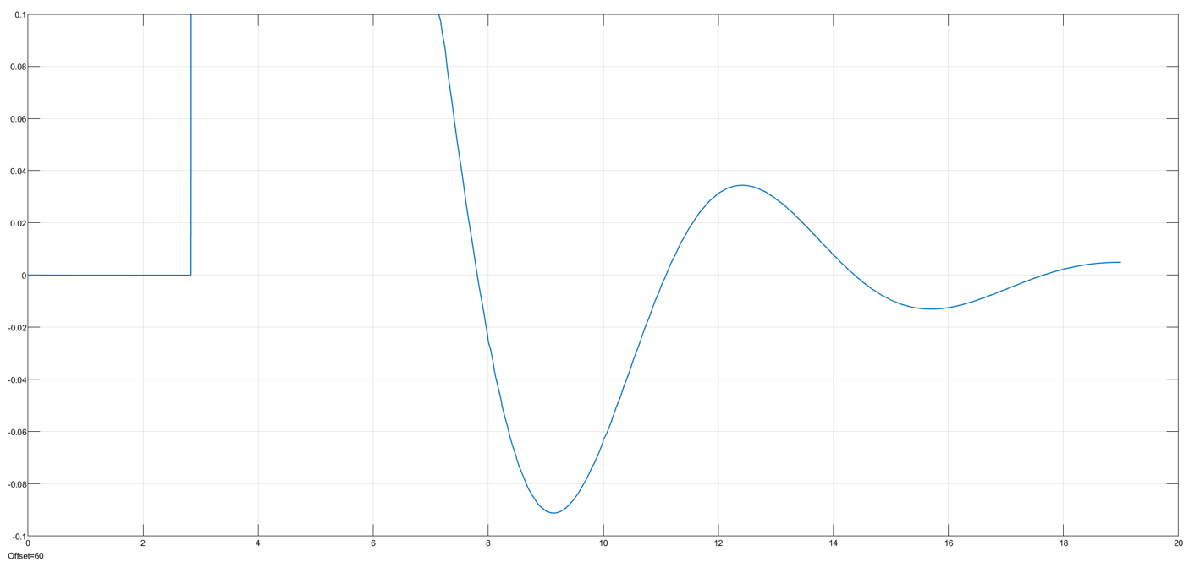

Esta segunda gráfica tiene el mismo comportamiento solamente que es para cuando la señal cuadrada tiende al valor 0.5.

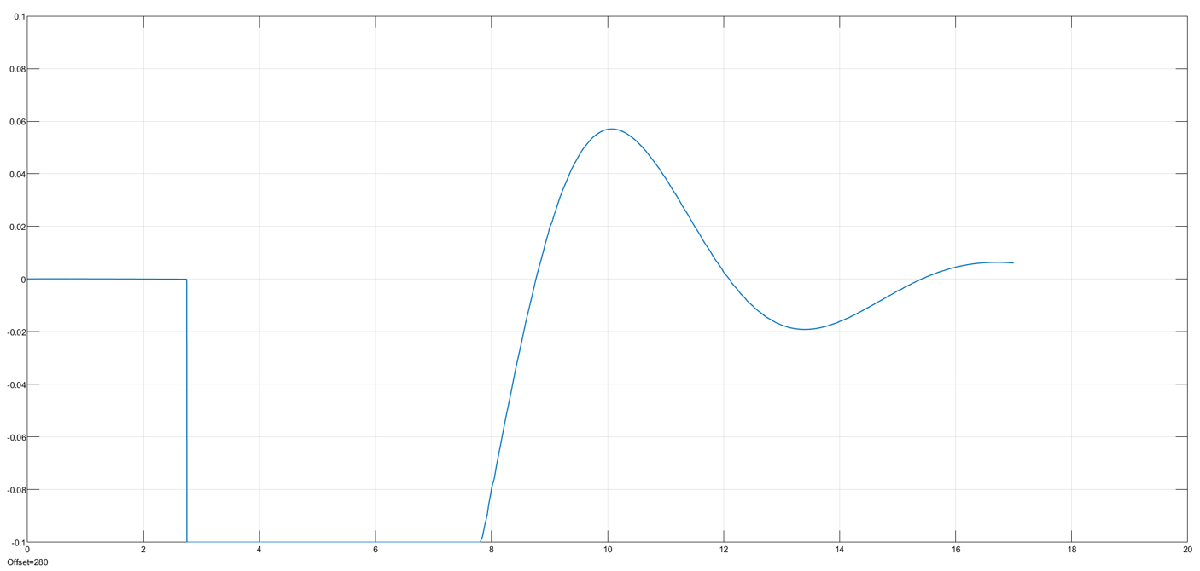

**Primera salida del subsistema water tank**

La primera salida del subsistema water tank es el nivel del agua, y podemos ver que la respuesta es menor estable que con el controlador pasado, ya que oscila mucho más, es decir, trata de llegar al valor deseado y no solo llega, sino que se pasa, y regresa, y así va cambiando entre dicho valor hasta que alcanza el deseado. Por tanto, la respuesta con el controlador lógico difuso es mejor. La gráfica con PID se muestra a continuación:

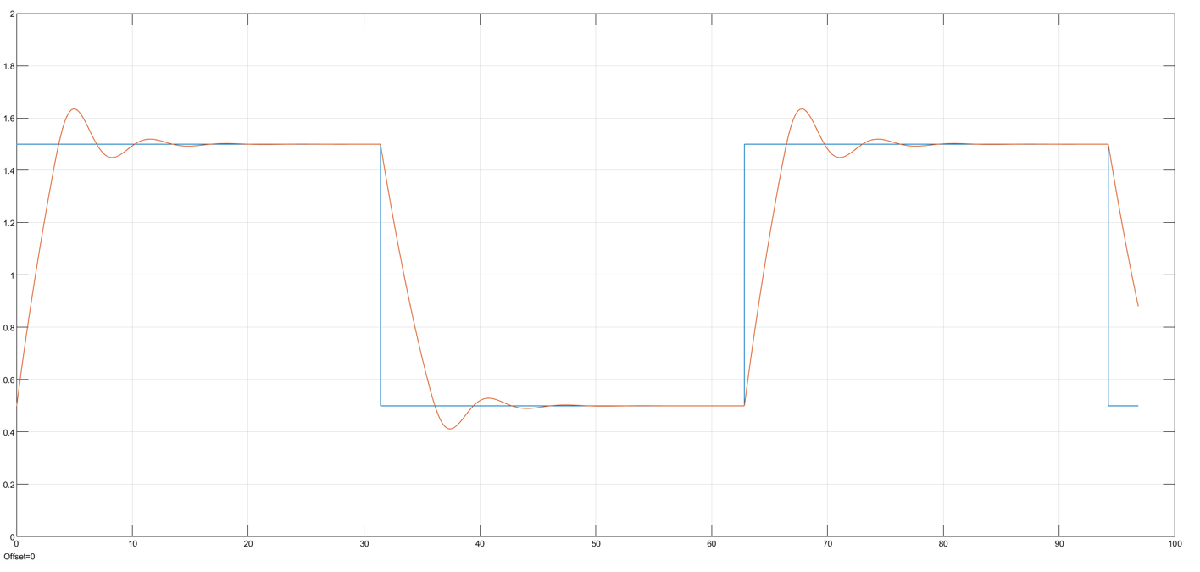

**Segunda salida del subsistema water tank**

Como se comentaba con el controlador anterior, esta segunda salida representa el volumen sobre tiempo del tanque, y como se ha dicho, cuando el nivel de agua se encuentra con un valor alto, esta gráfica tiene sus valores altos debido a la relación la fórmula presentada. No obstante, como para este controlador existe el hecho de que el nivel del agua sobrepasa el deseado, en esta gráfica también se ve reflejado, en donde la diferencia con la gráfica del otro controlador, en esta se presenta esos pequeños picos conforme la función aumenta o baja de valor, ocurren esos picos y luego ya se mantiene constante en un intervalo de tiempo, esto significa básicamente que el nivel de agua en ese pequeño tiempo se ha rebasado del deseado, es por eso que esto no se presenta en el anterior ya que ese suceso no pasaba.

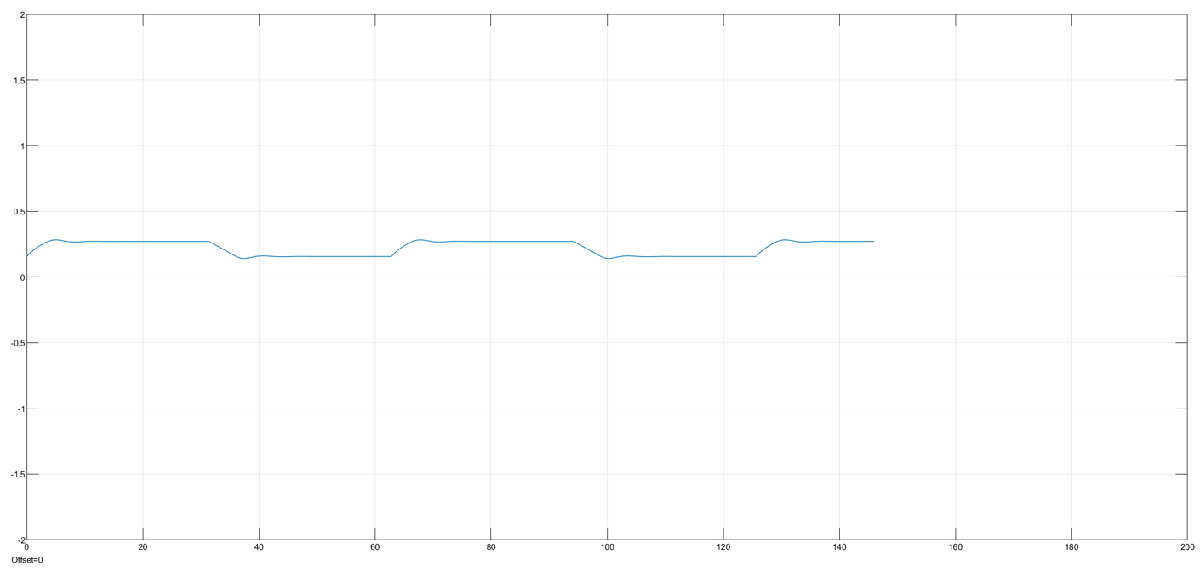

**Tercera salida del subsistema water tank**

Así como ocurría con el otro controlador, esta salida es el resultado de introducir el nivel de agua en un bloque relay, en donde ya se explicó su funcionamiento. El resultado de la gráfica para este caso, es el mismo que para el controlador lógico difuso.

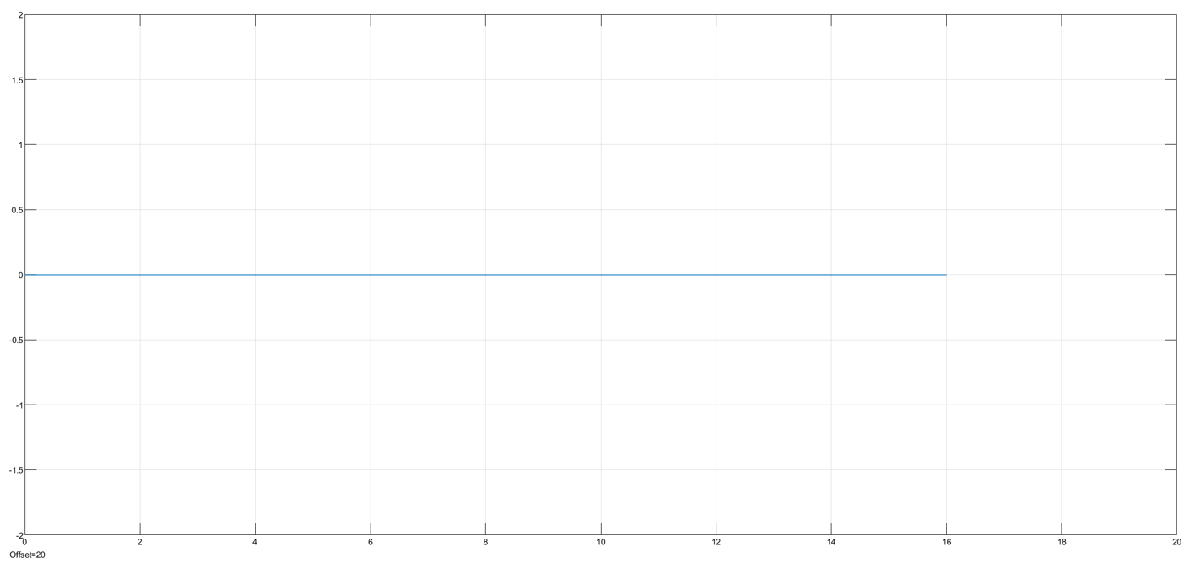

**Animación**

Al simular el sistema del tanque se muestra una animación del tanque físico en donde hay una barrita de color rojo que está mostrando el nivel deseado, mientras que el agua dentro del tanque simulado representa el nivel real del tanque y cómo actúa cada vez que se cambia de nivel deseado.

- **Controlador lógico difuso**

 Cuando se usa el controlador lógico difuso, ya sabemos el comportamiento por todas las gráficas presentadas previamente. La animación para este controlador es simple, cada vez que la señal de entrada cuadrada cambiaba de nivel deseado  , el agua lo hacía, subía para la barrita superior primero de manera rápida, y ya cuando se encuentra cerca del nivel deseado la velocidad bajaba. Así lo mismo para cuando el nivel deseado era de 0.5, el nivel de agua bajaba rápido y luego reducía la velocidad. 

Aquí se presentan dos figuras:

Cuando el agua baja para el nivel deseado bajo:

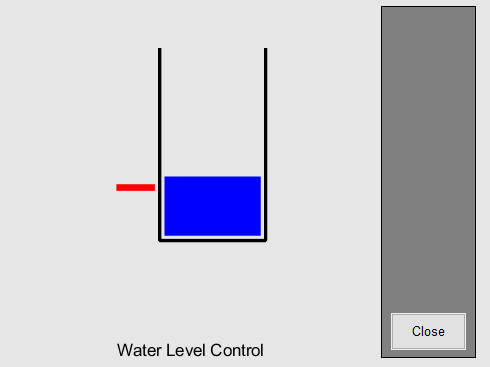

Cuando el agua sube para el nivel deseado alto:

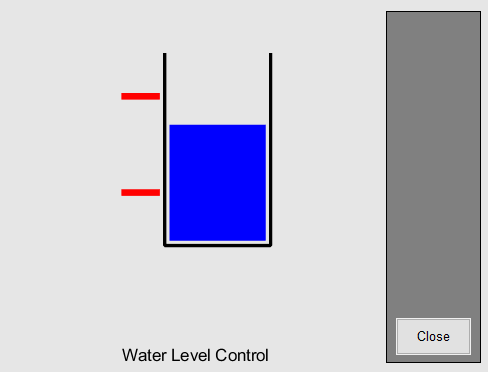

- **Controlador PID  **

La diferencia con este controlador ya se ha mencionado, y realmente se presentan las dos figuras en donde se presenta lo dicho: cuando el nivel del agua baja más de lo que se deseaba para cuando se quería el nivel inferior, y así con la otra parte, cuando el nivel del agua se pasaba por arriba del nivel de agua deseado.

En las siguiente figuras se muestra la animación:

 Cuando el agua baja más que el nivel mínimo deseado:

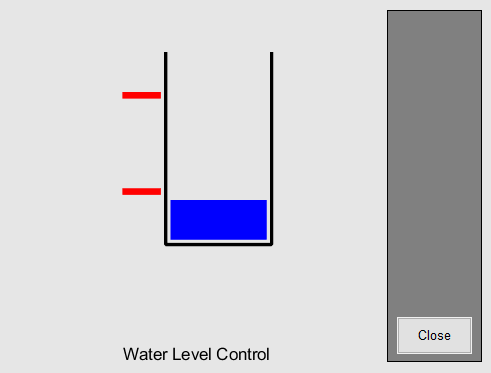

 Cuando el agua sube más que el nivel máximo deseado:

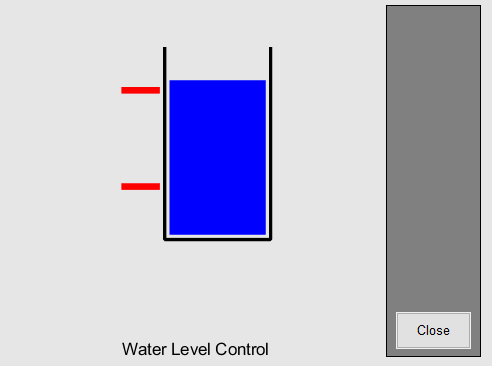

### Problema 3

La logica difusa se puede implementar en varias aplicaciones en ingeniería, tal es el caso de:

**Hela Lassoued, Raouf Ketata**, *Chapter 5 - Genetic fuzzy logic based system for arrhythmia classification*, Editor(s): Olfa Boubaker, Control Theory in Biomedical Engineering, Academic Press, 2020, Pages 105-127, ISBN 9780128213506. [Enlace](https://www.sciencedirect.com/science/article/pii/B9780128213506000056)

Contesta las siguentes preguntas respecto a la revisión del documento.

**3.1** **¿Qué factores explican la presencia de arritmias?**

Malos hábitos alimenticios, falta de actividad física, altos índices de estrés, por causas hereditarias, edad, entre muchos otros factores.

**3.2 ¿A qué se refieren las siglas DSS?**

Vienen del inglés *Decision Support System*. Son sistemas computacionales que tienen como objetivo ayudar a la toma de decisiones.

**3.3 ¿A qué se refieren las siglas FLC?**

Fuzzy logic controllers que en español se traduce como controladores de lógica difusa. 

**3.4**** ¿A qué se refieren las siglas GA?**

Las siglas se refieren a *Genetic Algorithm*.

**3.5 ¿Cuál es el principal objetivo del capítulo 5?**

El objetivo principal del capítulo 5 es mejorar la precisión de la SSD basada en la clasificación de las arritmias cardíacas.

**3.6****  La base de datos  *****MIT-BIH Arrhythmia Database***** contiene varios registros de distintos tipos de arritmias, ¿cuáles son estos?   **

Los datos se recuperaron del índice de símbolos que se utilizan en la base de datos [MIT-BIH Arrhythmia Database Directory (Introduction) (physionet.org)](https://physionet.org/files/mitdb/1.0.0/mitdbdir/intro.htm#symbols)

- AB: Bigeminismo auricular.

- AFIB: Fibrilación auricular.

- AFL: Aleteo auricular.

- B: Bigeminismo ventricular.

- BII: Bloqueo cardíaco de segundo grado.

- IVR: Ritmo idioventricular.

- LBBB: Obstrucción o retraso de los impulsos eléctricos en el lado izquierdo del corazón.

- NOD: Ritmo nodal (unión auriículo-ventricular).

- NSR: Ritmo sinusal normal.

- P: Ritmo acelerado.

- PREX: Síndrome de preexcitación (WPW).

- PVC: Contracción ventricular prematura.

- RBBB: Obstrucción o retraso de los impulsos eléctricos en el lado derecho del corazón.

- SBR: Bradicardia sinusal.

- SVTA: Taquiarritmia supraventricular.

- T: Trigeminismo ventricular.

- VFL: Aleteo ventricular.

- VT: Taquicardia ventricular.

**3.7 ¿De qué depende el desempeño de un FLC?**

Depende del ajuste de los parámetros en las funciones de membresía y las reglas en las que se basa.

**3.8**** ¿Para que utilizan un GA?**

El sistema tiene un diagrama de bloques similar al de un controlador estándar. En este caso el GA utiliza la señal de error para optimizar los parámetros de membresía, luego el FLC se actualiza con estos parámetros y se generan nuevas salidas. Este proceso se repite hasta que el error es de 0.

El GA se encarga de optimizar los parámetros de las funciones de membresía gaussiana y del número de reglas difusas.

**3.9 La Figura 1 muestra un diagrama de bloques de la metodología implementada para la clasificación de arritmias. En nuestro caso nos interesa el bloque de clasificación. Este está compuesto por configuración y optimización. ¿En qué consisten las entradas (input features) que recibe este bloque de clasificación? **

Las entradas en este bloque provienen de las mediciones que se hacen con un ECG donde se miden ciertos parámetros, después estos son filtrados y se toman los que se van a evaluar, luego son utilizados como entradas para FLC y así poder clasificar las mediciones en 5 arritmias. 

**3.10**** La principal ventaja de un FLC es que no es necesario un modelo matemático para la implementación del controlador (difuso). En general esto es el caso (como en el ejemplo del Problema 2), aunque puede suceder que para resolver cierta clase de problemas  sea necesario el modelo matemático de un subsistema. Se espera que la Figura 10 sea transparente en este momento. De acuerdo al texto ¿Cuál es la diferencia entre la inferencia de Mamdani y Sugeno?**

La principal diferencia es que en Mamdani el antecedente y el consecuente son variables difusas, mientras que en Sugeno el antecedente es una variable difusa y el consecuente es una constante o una función lineal.

**3.11 De la sección 2.2.1 FLC configuration, ¿Cuántas variables lingüísticas se tienen? ¿Qué tipo de conjuntos difusos son los consecuentes? ¿Cuántas reglas si-entones se proponen? ¿Qué sistemas de inferencia se utiliza? ¿Qué operaciones se utilizan para la Conjunción, Disyunción e Implicación?**

Tiene 6 variables lingüísticas las cuales son: frecuencia cardíaca media (E1), la amplitud de la onda P (E2), el intervalo de duración PR (E3), la duración del complejo QRS (E4), la duración del intervalo RR (E5) y la duración del intervalo ST (E6).

Los consecuentes son singletons.

Se proponen 5 reglas si-entonces. 

Se utiliza el sistema de inferencia Mamdani. 

Para la conjunción se utiliza el producto, para la disyunción se utiliza la suma y para la implicación se utiliza el producto.

**3.12**** Reporte el diagrama de flujo del GA utilizado.**

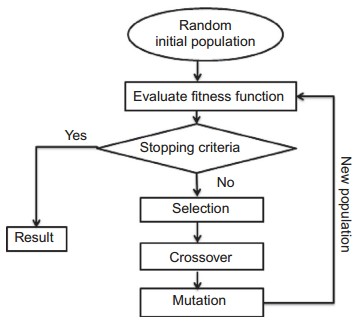

**3.13 Escriba la expresión matemática para la *****fitness function***** utilizada.**

**3.14 No se pretende profundizar sobre el funcionamiento del GA. Basta con tener una visión general de su uso en esta implementación, En particular los parámetros a optimizar se les da el nombre de *****cromosomas.***** En este caso ¿Qué representan los cromosomas? ¿Cuáles son los resultados del proceso de optimización?**

En los algoritmos genéticos, un individuo se caracteriza por un conjunto de parámetros o variables, cada una conocida como un gen. En este caso, los cromosomas están conformados por el número de reglas difusas y los parámetros $\mu$ y $\delta$ de las funciones de membresía gaussianas.

Como resultados se obtuvieron que el RMSE mínimo fue utilizando tres conjuntos difusos gaussianos y aplicando 62 reglas difusas.

**3.15 ¿Cuáles fueron los resultados de la implementación?**

El FLC se encarga de clasificar las señales del ECG en 5 arritmias, se evalúa comparando los resultados con sus objetivos, el error cuadrático medio (que es la función fitness), la precisión (ACC), sensibilidad (Se) y la especificidad nos ayudan a evaluar el rendimiento de la eficacia del FLC. Estas operaciones se definen como: 

Donde N es el número total de registros de ECG, NCC es el número total de latidos del corazón clasificados correctamente, TP (verdadero positivo) representa el número de personas enfermas clasificadas como enfermas, FP (falso positivo) representa el número de personas no enfermas clasificadas como enfermas, TN (verdadero negativo) representa el número de personas no enfermas clasificadas como no enfermas, y FN (falso negativo) representa el número de personas enfermas clasificadas como no enfermas.

## Apéndices

### Código utilizado en el problema 1.

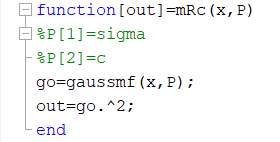

## Referencias

- *MIT-BIH Arrhythmia Database Directory (Introduction)*. (s. f.). MIT-BIH Arrhythmia Database Directory. Recuperado 15 de septiembre de 2021, de https://physionet.org/files/mitdb/1.0.0/mitdbdir/intro.htm#symbols